**Generating a QPS Spindle**

% Mean Values For QPS:
a = 0.82

a = 0.8200

b = 1.05

b = 1.0500

c = -10.0

c = -10

d = 0.0

d = 0

e = 84.5

e = 84.5000

f = -0.9

f = -0.9000


% Sampling Frequency:
fs = 256;
Ts = 1/fs;

% Time-Vector:
t = -1:Ts:1;

% Amplitude (QPS) Vector:
s = exp(a + b.*t + c.*t.^2) .* cos(d + e.*t + f.*t.^2)

s =    -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0002   -0.0002   -0.0002   -0.0001   -0.0001   -0.0000    0.0001    0.0002    0.0003    0.0003    0.0004    0.0004    0.0003    0.0002    0.0001   -0.0001   -0.0003   -0.0005   -0.0006   -0.0007   -0.0007   -0.0006   -0.0005   -0.0002    0.0001    0.0004    0.0008    0.0011    0.0013    0.0014



% Generate the envelope using Hilbert:
env = abs(hilbert(s))

env =     0.0001    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0006    0.0006    0.0007    0.0007    0.0008    0.0008    0.0009    0.0009    0.0010    0.0011    0.0011    0.0012    0.0013    0.0014


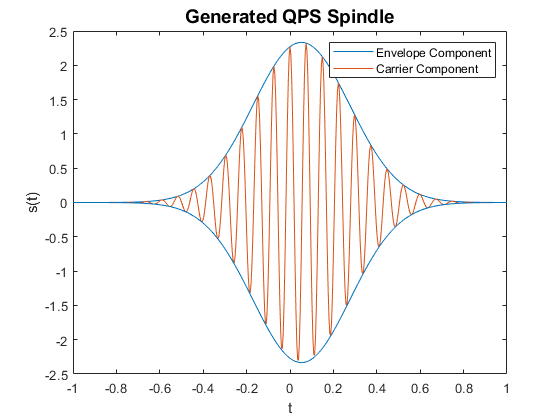


figure
plot(t,env, 'color', [0, 0.4470, 0.7410])
hold on
plot(t,s)
plot(t,-env, 'color', [0, 0.4470, 0.7410])
legend("Envelope Component", "Carrier Component")
title("Generated QPS Spindle", 'fontsize', 14)
xlabel("t")
ylabel("s(t)")